clc
close all
clear all
% set(gcf,'Visible','on')

syms m p w0

f = logspace(1,5,100);

w0 = 2*pi*1e3;
p = 1i*2*pi.*f;


m = (0.05:0.05:1/sqrt(2))';

H = 1./(1+2*m.*(p/w0)+(p.^2/w0^2));

Qdb = 0*m;
fr = 0*m;

for i = 1:1:length(m)
    H = subs(H);
    [M,I] = max(20.*log10(abs(H(i,:))))
    
    fr(i) = f(I);
    Qdb(i) = M;
end

$$M = \frac{20\,\log\left(\frac{\sqrt{633825300114114700748351602688}\,\sqrt{37275764485087931315173022132857}}{633825300114114700748351602688}\right)}{\log\left(10\right)}$$

I = 50

$$M = \frac{20\,\log\left(\frac{\sqrt{633825300114114700748351602688}\,\sqrt{14295123979258236969768912046505}}{633825300114114700748351602688}\right)}{\log\left(10\right)}$$

I = 50

$$M = \frac{20\,\log\left(\frac{\sqrt{225619057341846668285458447565005}}{4503599627370496}\right)}{\log\left(10\right)}$$

I = 50

$$M = \frac{20\,\log\left(\frac{\sqrt{527919333086448225077006488248145}}{9007199254740992}\right)}{\log\left(10\right)}$$

I = 50

$$M = \frac{20\,\log\left(\frac{\sqrt{2535301200456458802993406410752}\,\sqrt{10757262697406559973759293969129}}{2535301200456458802993406410752}\right)}{\log\left(10\right)}$$

I = 50

$$M = \frac{20\,\log\left(\frac{\sqrt{244633924256250495650262055308721}}{9007199254740992}\right)}{\log\left(10\right)}$$

I = 49

$$M = \frac{20\,\log\left(\frac{\sqrt{188683608073031724942638364707809}}{9007199254740992}\right)}{\log\left(10\right)}$$

I = 49

$$M = \frac{20\,\log\left(\frac{\sqrt{2346193456898758641119231359609}}{1125899906842624}\right)}{\log\left(10\right)}$$

I = 48

$$M = \frac{20\,\log\left(\frac{\sqrt{10141204801825835211973625643008}\,\sqrt{15672599065961109041031377926253}}{10141204801825835211973625643008}\right)}{\log\left(10\right)}$$

I = 48

$$M = \frac{20\,\log\left(\frac{\sqrt{6756677164475820411255786223669}}{2251799813685248}\right)}{\log\left(10\right)}$$

I = 47

$$M = \frac{20\,\log\left(\frac{\sqrt{95983725943828399993978578428285}}{9007199254740992}\right)}{\log\left(10\right)}$$

I = 45

$$M = \frac{20\,\log\left(\frac{\sqrt{10141204801825835211973625643008}\,\sqrt{10999886009435370933850377191657}}{10141204801825835211973625643008}\right)}{\log\left(10\right)}$$

I = 44

$$M = \frac{20\,\log\left(\frac{\sqrt{83111802461859171038678874330161}}{9007199254740992}\right)}{\log\left(10\right)}$$

I = 40

$$M = \frac{20\,\log\left(\frac{\sqrt{1298589930206705019106583181143585}}{36028797018963968}\right)}{\log\left(10\right)}$$

I = 29

A = ((2*pi*fr)/w0).^2

A =     0.9112
    0.9112
    0.9112
    0.9112
    0.9112
    0.7565
    0.7565
    0.6280
    0.6280
    0.5214


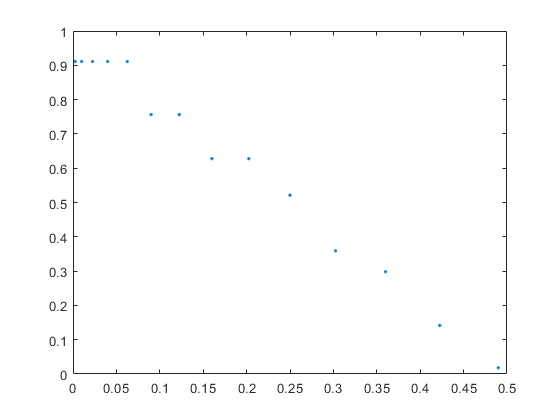


plot(m.^2,A,'.');

% fr = (w0/2pi)sqrt(-2m²)
p = polyfit(m.^2,A,1)

p =    -1.8967    0.9626


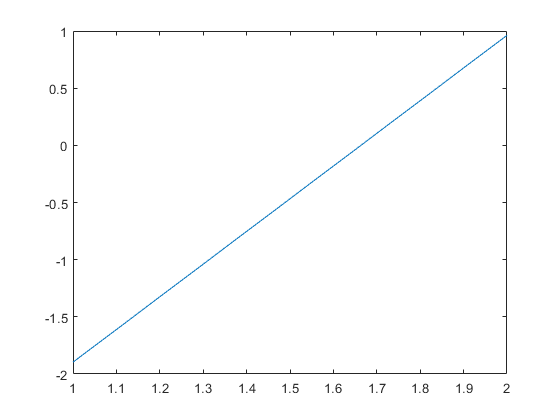

plot(p);


Q = 10.^(Qdb/20)

Q =     7.6688
    4.7491
    3.3352
    2.5509
    2.0599
    1.7365
    1.5250
    1.3604
    1.2432
    1.1543


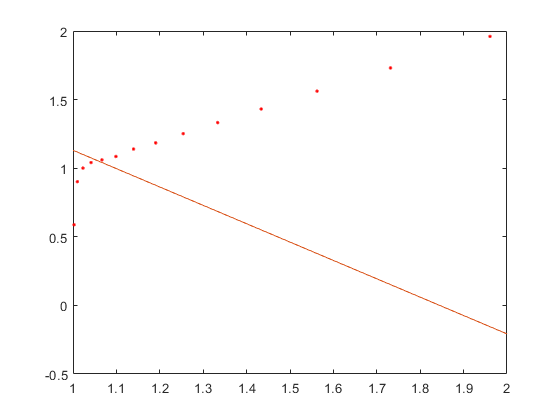

plot(1./(1-m.^2),(2*Q.*m).^2,'.r');
hold on
q = polyfit(1./(1-m.^2),(2*Q.*m).^2,1);
plot(q);